%This script is used to get 108 random deltas from database of Nienhuis et al. 2020
%Creates random vector size 108, with seed 100 to generate same deltas each time it is run.
%GlobalDeltaData.mat, EE_108randomdeltas_ordered.csv, EE_44polys_change.csv
%are necessary for this script to run

rng(100) % seeds the random number generator with an arbitrary number (100) to get the same deltas each time
randomdeltas = randperm(10848, 108);

% 
load('GlobalDeltaData.mat');

%Get River mouth location & Buffer 
%MouthLon_rand = MouthLon(randomdeltas);
%MouthLat_rand = MouthLat(randomdeltas);
%BasinID_rand = BasinID(randomdeltas);
%EE_108randomdeltas = table(BasinID_rand); %This table was used to check
%the 108 features in Earth Engine.

%Import 108 random deltas table
%GlobalDeltaData.mat from Nienhuis et al., 2020 needs to be imported
random108 = readtable('EE_108randomdeltas_ordered.csv'); %reads user filled-in table after check

%Get 44randomdeltas
random44poly = random108(random108.Polygon == 1, :);

%Import EE change into random44poly table
random44poly_change = readtable('EE_44polys_change.csv'); %loads Aqua changes obtained in EE

%EE_44polys_change.csv can be obtained by running the EE script located at:
%https://code.earthengine.google.com/1c074d96779371d7bf20922916ca22f9

%Add change to random44poly
[~,idrandom] = ismember(random44poly.BasinID, random44poly_change.BasinID); 
random44poly.change = random44poly_change.change2(idrandom)/28; %get yearly rates
random44poly.ero = random44poly_change.erosion2(idrandom)/28;
random44poly.dep = random44poly_change.deposition2(idrandom)/28;

%Add change from original Nienhuis buffers 
% ee from GlobalDeltaData.mat (Nienhuis et al., 2020) needs to be loade first
[~,idrandom_orig] = ismember(random44poly.BasinID, BasinID); %get index for random44poly deltas in BasinID
random44poly.change_original = ee.net_aqua(idrandom_orig);
random44poly.ero_original = ee.ero_aqua(idrandom_orig);
random44poly.dep_original = ee.dep_aqua(idrandom_orig);

%Compare net change
sum(random44poly.change) %not whole story

ans = 0.6065

sum(random44poly.change_original)

ans = 0.2093


%Create sorted min to max (based on original change) random44poly table
random44poly_sortchange = sortrows(random44poly,'change_original');
random44poly_sortchange = random44poly_sortchange([2 4:44 1 3], :); % move ee_delta 77 and 63 at end due to big new change value

%Make scatter plot
% clf
% figure
% scatter(random44poly.change_original, random44poly.change)
% xlim ([-0.05 0.3])
% line([xlim], [ylim],'Color','r')
% xlabel 'original net change (km^2/yr)'
% ylabel 'new net change (km^2/yr)'
% title '44 poly change comparrison'
% text (0.27, 0.25, '1:1 line')
random44_fit = fitlm(random44poly.change_original, random44poly.change) %R^2 = 0

random44_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat     pValue 
                   ________    _________    _______    _______

    (Intercept)    0.013172    0.0080208     1.6422    0.10802
    x1              0.12889      0.39253    0.32836    0.74427


Number of observations: 44, Error degrees of freedom: 42
Root Mean Squared Error: 0.0517
R-squared: 0.00256,  Adjusted R-Squared -0.0212
F-statistic vs. constant model: 0.108, p-value = 0.744

% text (0.18, 0.05, 'R^2 = 0 (all)')


%sum_original108 = sum
%sum_new108
%Get statistics for 44 poly
difference = random44poly.change_original./random44poly.change .*100;%calculate difference in (%)
difference100 = sum(difference < 100 & difference > -100)

difference100 = 24

difference100(2) = difference100 ./ 44 * 100 %Get percentage

difference100 =    24.0000   54.5455


difference50 = sum(difference < 50 & difference > -50)

difference50 = 14

difference50(2) = difference50 ./ 44 * 100 %Get percentage

difference50 =    14.0000   31.8182


diff_pos_to_neg = sum(difference < 0)%counts deltas that got changed sign net area change

diff_pos_to_neg = 10

diff_pos_to_neg(2) = diff_pos_to_neg ./ 44 * 100

diff_pos_to_neg =    10.0000   22.7273



%Get 108 deltas net change sum:
[~,idrandom_108] = ismember(random108.BasinID, BasinID);
random108_sum = sum(ee.net_aqua(idrandom_108));

sum(random44poly.change_original) 

ans = 0.2093

sum(random44poly.change)

ans = 0.6065

NRMSE_mean = 0.05./mean(random44poly.change)

NRMSE_mean = 3.6272

NRMSE_sd = 0.05./std(random44poly.change)

NRMSE_sd = 0.9765

%Get number of delta classification and indexes
no_detlas_original = 108;
no_polygons = sum(random108.Polygon);%44
no_deltas = sum(random108.Delta);%57
no_deltas(2) = no_deltas ./ 108 * 100;% 53% are deltas

% Get no of polygons and % of anthropogenic influence, high interior
% change, small bufffer and overlapping buffers
no_polygons_Anthropogenic = sum(random44poly.Anthropogenic); %get no 
no_polygons_Anthropogenic(2) = no_polygons_Anthropogenic ./ no_polygons * 100; %get percentage
no_polygons_Anthropogenic_filtering = nansum(random44poly.Anthropogenic_filtering_succesful_Landcover); 

no_polygons_High_interior_change = sum(random44poly.Interior_change);
no_polygons_High_interior_change (2) = no_polygons_High_interior_change ./ no_polygons * 100;

no_polygons_Small_buffer = sum(random44poly.Small_or_misplaced_buffer);
no_polygons_Small_buffer(2) = no_polygons_Small_buffer ./ no_polygons * 100;

no_deltas_overlap = nansum(random108.Buffer_Overlaps_or_Inside_another_delta);
no_deltas_overlap(2) = no_deltas_overlap ./ 108 * 100;

%Get idx
idx_polygons_Anthropogenic = find(random44poly_sortchange.Anthropogenic == 1);
idx_polygons_High_interior_change = find(random44poly_sortchange.Interior_change== 1);
idx_polygons_Small_buffer = find(random44poly_sortchange.Small_or_misplaced_buffer == 1);
%idx_deltas_overlap = find(random44poly_sortchange.Buffer_Overlaps_or_Inside_another_delta == 1);

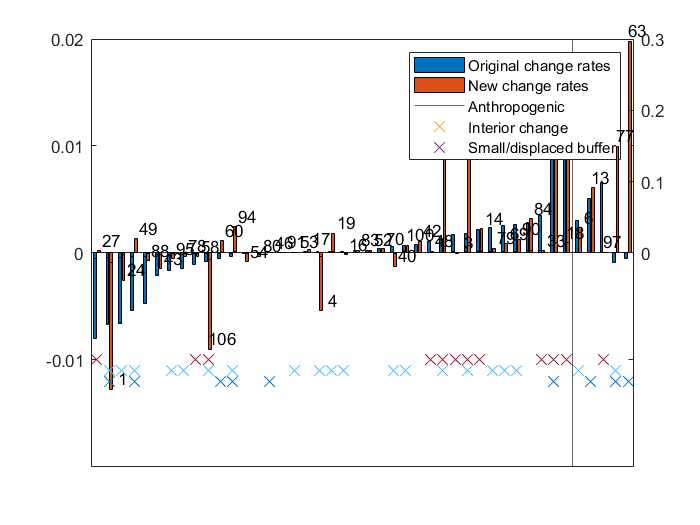

%Bar graph with two y axis
bary_rand44 = random44poly_sortchange.change_original;
bary_rand44(:,2) = random44poly_sortchange.change;

clf
figure(1)

ax = plotyy(1:39,bary_rand44(1:39,:),1:44,bary_rand44(1:44,:),@bar,@bar);
linkaxes(ax,'x')
ylim(ax(2), [-0.3 0.3]);
yticks ([[] -0.01 0 0.01 0.02])
yticks (ax(2), [ [] [] 0 0.1 0.2 0.3])
xticks ([])

text([1:39], random44poly_sortchange.change(1:39), num2str(random44poly_sortchange.EE_Delta_no(1:39)),'VerticalAlignment','bottom')
text(ax(2),[39:44], random44poly_sortchange.change(39:44), num2str(random44poly_sortchange.EE_Delta_no(39:44)),'VerticalAlignment','bottom')
xline(39.5);
%title('Delta change comparrison (km^2/yr)')
hold on

plot(idx_polygons_Anthropogenic, zeros(numel(idx_polygons_Anthropogenic))-0.01, 'x', 'MarkerSize', 9)
plot(idx_polygons_High_interior_change, zeros(numel(idx_polygons_High_interior_change))-0.011, 'x', 'MarkerSize', 9)
plot(idx_polygons_Small_buffer, zeros(numel(idx_polygons_Small_buffer))-0.012, 'x', 'MarkerSize', 9)
hold off
legend 'Original change rates' 'New change rates' 'Anthropogenic' 'Interior change' 'Small/displaced buffer'

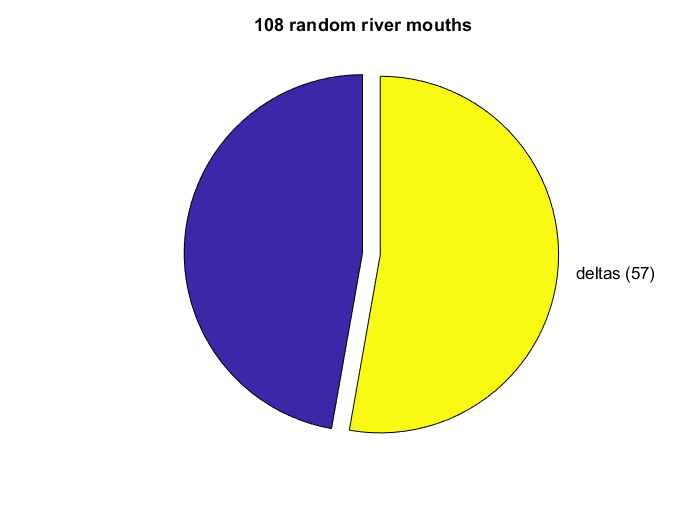

%Create pie plot
clf
figure
pie([108-no_deltas(1) no_deltas(1) ], [0 1], {'' 'deltas (57)'})
title '108 random river mouths'